close all; clc; clear all;
%Inputting file :
fprintf('Input File : \n')

Input File : 


Image type = Gray Image


Requested image : 


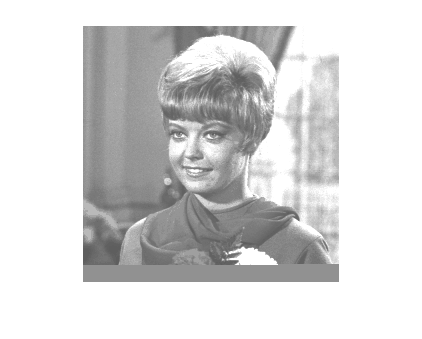

filename = "D:\dat d\Document\Itb\Semester 11\Pemrosesan Citra\Tugas 1\Uji Program Problem 4\girl.bmp";
if filename ~= ""
    image = imread(filename);
    
    %Pre-Processing
    [a,b,c] = size(image);
    
    if c == 3
        layer12 = (image(:,:,1) == image(:,:,2));
        layer23 = (image(:,:,2) == image(:,:,3));
        layer13 = (image(:,:,1) == image(:,:,3));
        layer = layer12 & layer13 & layer23;
    end
    
    if c == 1
        mode = "Gray Image";
    elseif c == 3
        if layer == 1 
            mode = "Gray Image";
            image = image(:,:,1);
        else
            mode = "RGB Image";
        end
        
    end
    
    fprintf('Image type = %s\n', mode)
    fprintf('Requested image : \n')
    figure, imshow(image)
end

Request from user : Histogram Specification


Insert the reference image to be used : 


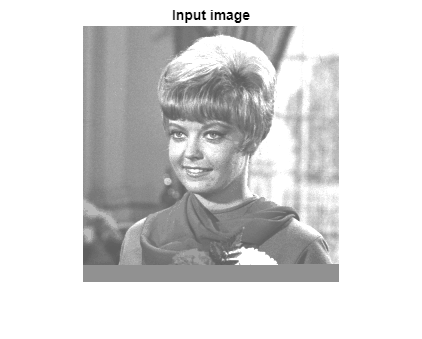

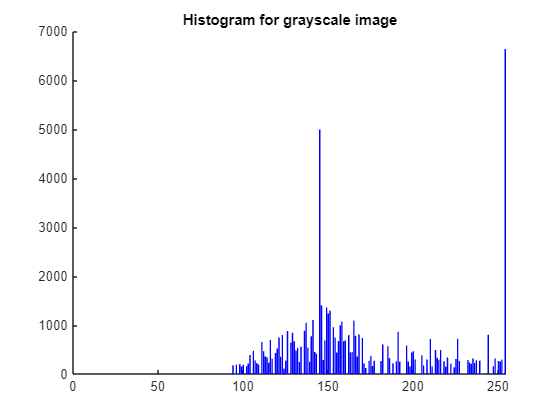

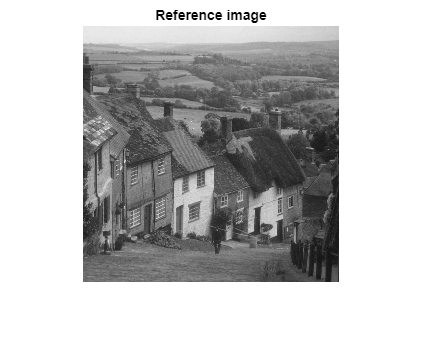

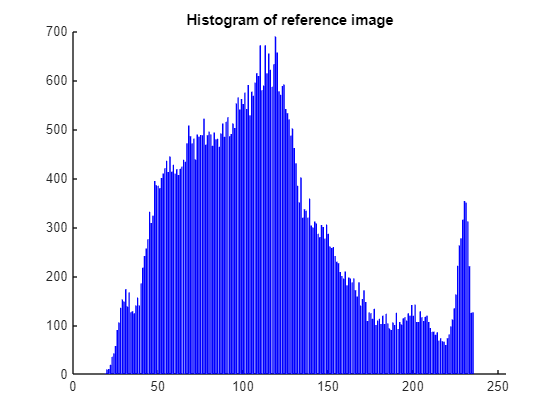

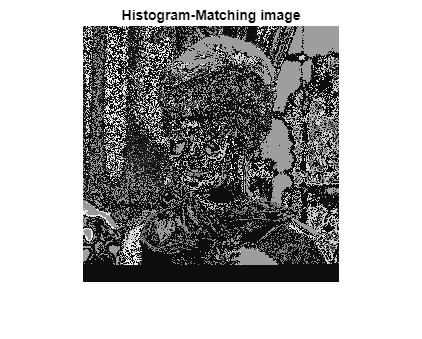

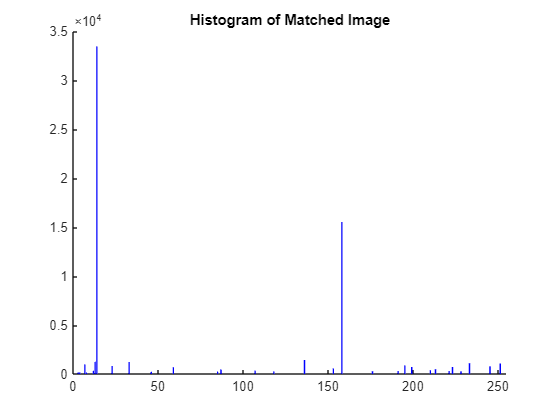

%Prompt from user
user_request = "Histogram Specification";
if user_request ~= "Select"
    fprintf('Request from user : %s\n', user_request)

    %Executing request from user
    if user_request == "Find Image Histogram"
        %Displaying results : 
        Display_Histogram(image, mode)

    elseif user_request == "Basic Image Enhancement"
        image_enhancement_type = "Select"

        if image_enhancement_type ~= "Select"
            image_new = image_enhancement(image, image_enhancement_type, mode);
            
            %Displaying results : 
            Display_Histogram(image, mode) 
            figure, imshow(image_new), title('Enhanced image')
            Display_Histogram(image_new, mode)
        end

    elseif user_request == "Histogram Equalization"
        image_new = image_hist_equalization(image, mode);

        %Displaying results : 
        Display_Histogram(image, mode)
        figure, imshow(image_new), title('Equalized image')
        Display_Histogram(image_new, mode)

    elseif user_request == "Histogram Specification"
        fprintf('Insert the reference image to be used : \n')
        filename_ref = "D:\dat d\Document\Itb\Semester 11\Pemrosesan Citra\Tugas 1\Uji Program Problem 4\goldhill.bmp";
        image_ref = imread(filename_ref);
        image_new = hist_matching(image, image_ref, mode);

        %Displaying results : 
        figure, imshow(image), title('Input image')
        Display_Histogram(image, mode)
        figure, imshow(image_ref), title('Reference image')
        Display_Histogram(image_ref, mode), title('Histogram of reference image')
        figure, imshow(image_new), title('Histogram-Matching image')
        Display_Histogram(image_new, mode), title('Histogram of Matched Image')
    end
end